clc;clear;

% 打开原文件和新文件
fid_in = fopen('.\Data\ev_dif\f4.log', 'r')

fid_in = 3

fid_out = fopen('.\Data\ev_dif\f4.txt', 'w')

fid_out = 4


% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

处理完成！


% 读取文本文件
filename = '.\Data\ev_dif\f2.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);


fid = fopen('.\Data\ev_dif\f2.txt', 'r'); %这样读入
if fid == -1
    error('File data.txt not found. Please ensure the file exists.');
end
data = fread(fid, '*char')';
fclose(fid);


% Extract all RX Timestamps
rx_pattern = 'RX Timestamp: (\d+)';
rx_matches = regexp(data, rx_pattern, 'tokens');
if isempty(rx_matches)
    error('No RX Timestamps found in the data.');
end
%这里的rx_matches是返回所有匹配rx_pattern的数组、
rx_timestamps = zeros(length(rx_matches), 1);
for i = 1:length(rx_matches)
    rx_timestamps(i) = str2double(rx_matches{i}{1});
end
rx_timestamps

rx_timestamps = 1.0e+12 *

    0.1029
    0.1061
    0.2470
    0.2502
    0.3911
    0.3943
    0.5353
    0.5385
    0.6794
    0.6827


% Extract all Clock Offset Hz values
co_pattern = 'Clock Offset: ([\d\.]+) Hz';
co_matches = regexp(data, co_pattern, 'tokens');
if isempty(co_matches)
    error('No Clock Offset values found in the data.');
end
clock_offsets = zeros(length(co_matches), 1);
for i = 1:length(co_matches)
    clock_offsets(i) = str2double(co_matches{i}{1});
end

clock_offsets

clock_offsets = 1.0e+03 *

    4.3181
    4.2921
    5.3521
    5.2926
    4.7235
    4.4334
    5.3038
    4.5153
    5.7092
    3.8235



num_rounds  = length(co_matches) / 2;
clock_CFO = zeros(1,num_rounds);
for i = 1:num_rounds
    clock_CFO(i) = ( clock_offsets(2*i-1) + clock_offsets(2*i) )/2;
end

clock_CFO

clock_CFO = 1.0e+03 *

    4.3051    5.3224    4.5785    4.9095    4.7663    4.7235    5.7705    5.1290    4.4520    5.2591    4.7905    4.5506    5.0453    5.3149    4.8481    4.6306    3.7826    5.0787    5.2796    5.6329    4.8017    5.2164    4.1805    4.8221    5.3335    4.6399    5.3893    4.2419    5.0099    4.3163    5.0416    4.3851    4.7607    4.4948    4.8630    5.2089    4.9783    4.9448    5.0453    4.7440    4.9095    4.7552    4.7961    5.2108    5.0769    4.3944    5.0676    5.1829    5.1569    4.6733


% 获取行内容
lines = rawData{1};

% 初始化存储变量
sn_len = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认
sn_len

sn_len =    130   131   175   176   220   221     9    10    54    55    99   100   144   145   189   190   234   235    23    24    68    69   113   114   158   159   203   204   248   249    37    38    82    83   127   128   172   173   217   218     6     7    51    52    96    97   141   142   186   187


disp(['Sequence Number: ', num2str(sn_len)]);

Sequence Number: 130  131  175  176  220  221    9   10   54   55   99  100  144  145  189  190  234  235   23   24   68   69  113  114  158  159  203  204  248  249   37   38   82   83  127  128  172  173  217  218    6    7   51   52   96   97  141  142  186  187  231  232   20   21   65   66  110  111  155  156  200  201  245  246   34   35   79   80  124  125  169  170  214  215    3    4   48   49   93   94  138  139  183  184  228  229   17   18   62   63  107  108  152  153  197  198  242  243   31   32   76   77  121  122  166  167  211  212    0    1   45   46   90   91  135  136  180  181  225  226   14   15   59   60  104  105  149  150  194  195  239  240   28   29   73   74  118  119  163  164  208  209  253  254   42   43   87   88  132  133  177  178  222  223   11   12   56   57  101  102  146  147  191  192  236  237   25   26   70   71  115  116  160  161  205  206  250  251   39   40   84   85  129  130  174  175  219  220    8    9   53   54   98   99  143  144  188

packets_num = floor(length(STS0_CIR)/512);  % 向下取整，确保能reshape成功
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

%有一个奇怪的现象，sequence number每一轮的开头分别是偶数->奇数->偶数，但是rx_timestamps基本是对的
packets_num

packets_num = 348

% 如果 packets_num 是奇数，丢弃最后一行
i = 1

i = 1

while i < packets_num
    % 判断当前数据包索引i是否为偶数
        % 交换STS0_CIR的第i行和第i+1行
     if mod(sn_len(i),2) == 1
     temp = STS0_CIR(i, :);
     STS0_CIR(i, :) = STS0_CIR(i+1, :);
     STS0_CIR(i+1, :) = temp;
     
        % 交换STS1_CIR的第i行和第i+1行
     temp = STS1_CIR(i, :);
     STS1_CIR(i, :) = STS1_CIR(i+1, :);
     STS1_CIR(i+1, :) = temp;

     temp = rx_timestamps(i,:);
     rx_timestamps(i,:) = rx_timestamps(i+1,:);
     rx_timestamps(i+1,:) = temp; %这是进行时间戳的交换
     end

    % 移动到下一组数据包
    i = i + 2;
end

rx_timestamps

rx_timestamps = 1.0e+12 *

    0.1029
    0.1061
    0.2502
    0.2470
    0.3911
    0.3943
    0.5385
    0.5353
    0.6794
    0.6827



if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];
    STS1_CIR(end, :) = [];
    packets_num = packets_num - 1 ;
end
packets_num

packets_num = 348


aod_errors = zeros(1, num_rounds);
test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的
for i = 1:num_rounds
    idx1 = 2*i - 1;
    idx2 = 2*i;
    T1 = rx_timestamps(idx1);
    T2 = rx_timestamps(idx2);
    CFO = clock_CFO(i); % 使用每轮第一个数据包的Clock Offset
    
    delta_t = (T2 - T1) / 1e12 ; % 转换为秒
    test_time(i) = delta_t;
    aod_errors(i) = 0.000154 * 2 * pi * delta_t * CFO *180 / pi; % 计算AOD_error
end
aod_errors

aod_errors =     0.7651   -0.9445    0.8129   -0.8719    0.8466   -0.8387    1.0246   -0.9110    0.7909   -0.9342    0.8510   -0.8080    0.8959   -0.9439    0.8610   -0.8226    0.6717   -0.9019    0.9377   -1.0008    0.8530   -0.9267    0.7427   -0.8566    0.9477   -0.8246    0.9571   -0.7534    0.8900   -0.7667    0.8956   -0.7793    0.8460   -0.7984    0.8639   -0.9256    0.8846   -0.8784    0.8961   -0.8418    0.8720   -0.8441    0.8518   -0.9256    0.9016   -0.7807    0.9001   -0.9204    0.9164   -0.8299


c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;
% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72
dis = sqrt((4.4-4.01)*(4.4-4.01) + (2.2-2.01) * (2.2-2.01))

dis = 0.4338

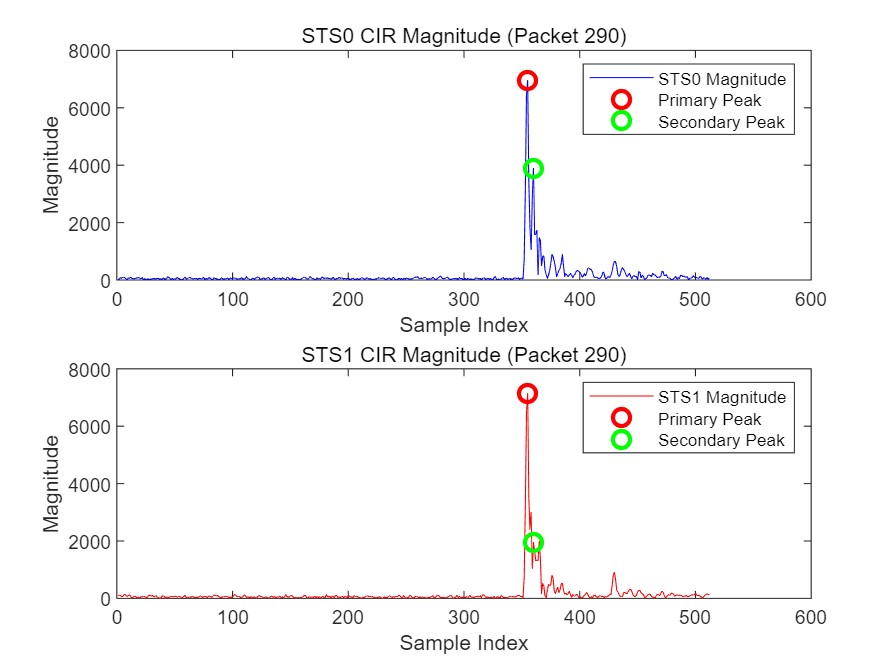

aoa_pdoa_values_main = [];
aoa_degree_values_main = [];

aoa_pdoa_values_secondary = [];
aoa_degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];

for i = 1:packets_num
    % i =2 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;  % 阈值
    min_peak_distance = 4;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue; % 跳过不满足条件的帧
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index2_STS0 = locs_STS0(2);
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);


    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0,peak_index2_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1,peak_index2_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS1));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    aoa_pdoa_values_main(1,end+1) = phase_difference_main;
    aoa_degree_values_main(1,end+1) = theta_degrees_main;
    
    %% ---- 次强峰相位差计算 ----
    STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
    STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
    phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
    phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;

    theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_secondary = rad2deg(theta_radians_secondary);

    aoa_pdoa_values_secondary(1,end+1) = phase_difference_secondary;
    aoa_degree_values_secondary(1,end+1) = theta_degrees_secondary;

    % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');
    % 
    % % 把当前帧写入视频
    % frame = getframe(gcf);
    % writeVideo(v, frame);
end

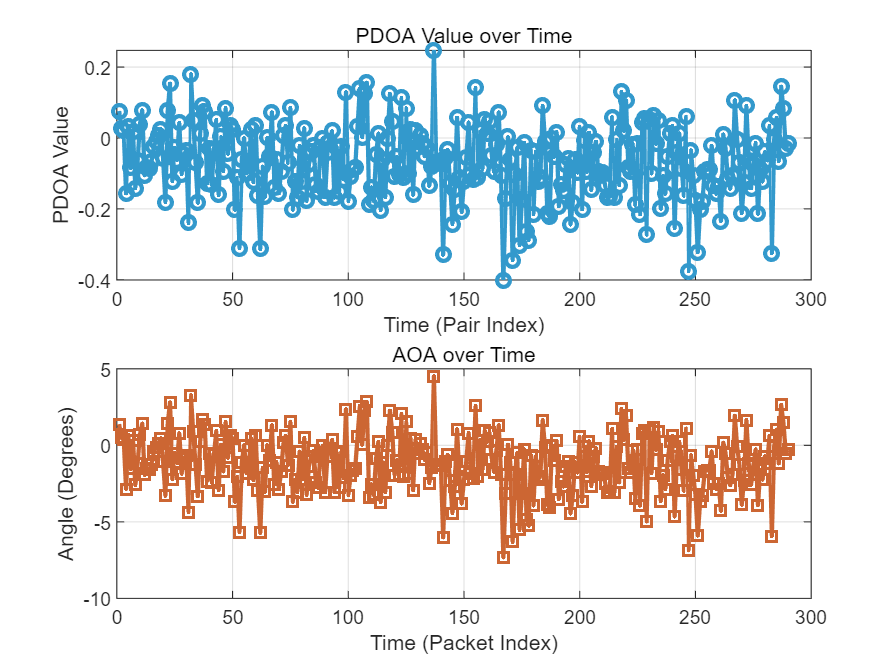

time = 1:length(aoa_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aoa_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aoa_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aoa_pdoa_values_main);
mean_degree = mean(aoa_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aoa_pdoa_values_main);
std_degree = std(aoa_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.07


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.11



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: -1.22


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 1.93


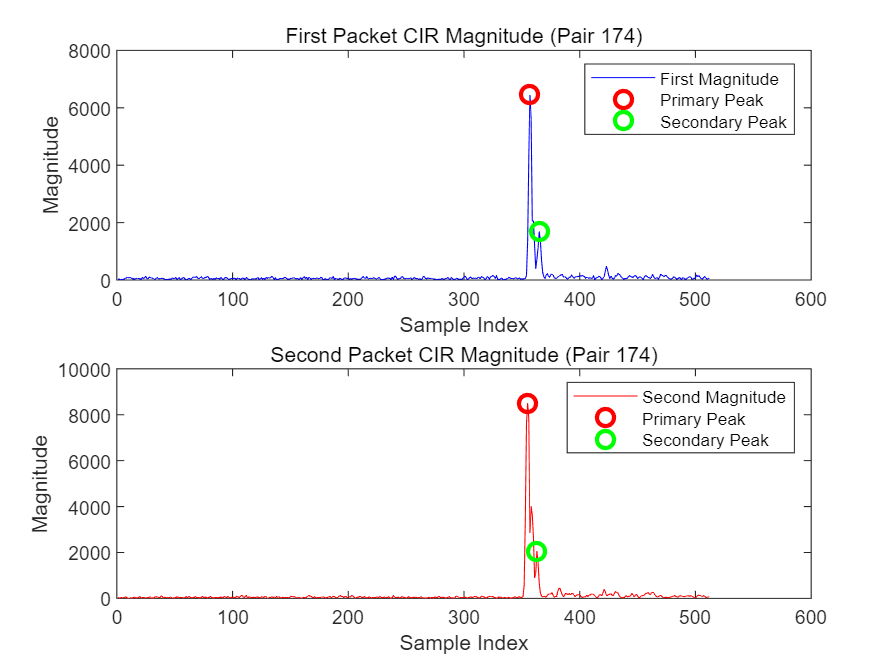

first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

aod_pdoa_values_main = [];
aod_degree_values_main = [];

aod_pdoa_values_secondary = [];
aod_degree_values_secondary = [];

peaks_index_first = [];
peaks_index_second = []; %需要在这里把aod_pdoa_values的main和secondary整体减去误差

% video_filename = 'AOD_3.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);


num_pairs = size(first_packet_cir, 1);  % 每组两个packet

for i = 1:num_pairs
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 4;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_first) < 2 || length(locs_second) < 2
        continue; % 跳过不满足条件的帧
    end

    peak_index1_first = locs_first(1);
    peak_index2_first = locs_first(2);

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);

   
    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first];
    peaks_index_second = [peaks_index_second; peak_index1_second, peak_index2_second];

    % ---- 主峰相位差计算 ----
    phase_first_main = angle(first_data(peak_index1_first));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main ;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;

    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;

    % ---- 次强峰相位差计算 ----
    phase_first_sec = angle(first_data(peak_index2_first));
    phase_second_sec = angle(second_data(peak_index2_second));
    phase_diff_sec = phase_second_sec - phase_first_sec;
    phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;

    theta_rad_sec = asin(phase_diff_sec * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_sec = rad2deg(theta_rad_sec);

    aod_pdoa_values_secondary(end+1) = phase_diff_sec;
    aod_degree_values_secondary(end+1) = theta_deg_sec;

    % ---- 画图 ----
    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Primary Peak', 'Secondary Peak');

    % frame = getframe(gcf);
    % writeVideo(v, frame);
end


fprintf("This is the length of pdoa_main %d",length(aod_pdoa_values_main));

This is the length of pdoa_main 174

% close(v);
% disp(['视频已保存为: ', video_filename]);

figure;
pd = diff(aod_pdoa_values_main)

pd =     3.5674   -3.8181    6.3882   -4.1103    6.0338   -2.6124    6.5301   -1.8549    2.3876   -2.4598    6.2194   -5.8486    1.1046   -1.7259    2.6091   -0.1918    5.1176   -1.6959    5.7979   -3.1119    0.4814   -2.6653    4.2580   -0.6997    1.7661   -2.7235    3.7727   -4.3915    4.6896   -5.2630    1.4035   -3.7487    4.6022   -0.3995    3.3527   -6.2163    1.6097   -3.4330    0.9197   -0.8261    3.5640   -3.8147    5.9304   -0.7725    1.7536   -2.9457    5.0443   -6.0751    5.3512   -5.6935


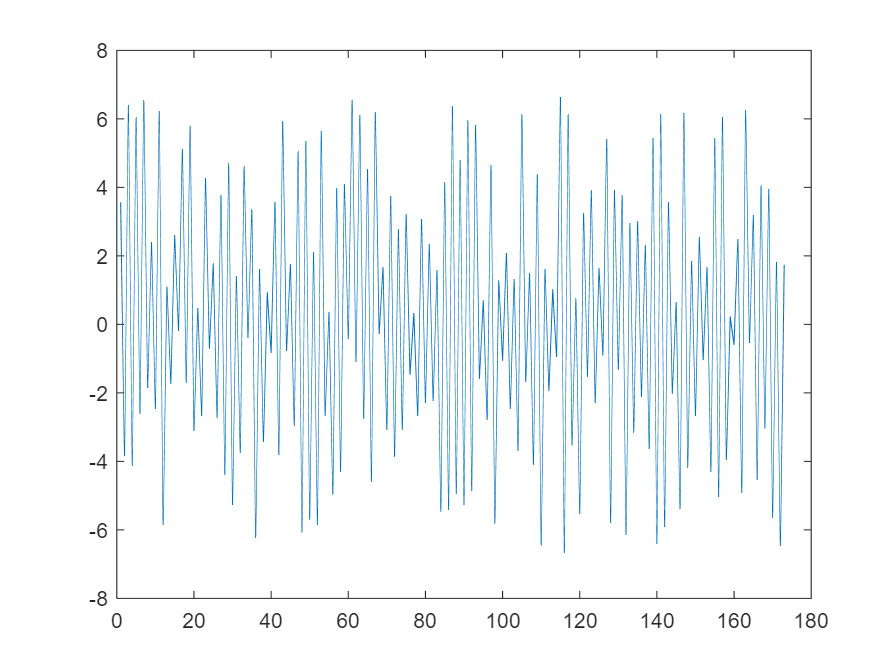

plot(pd)

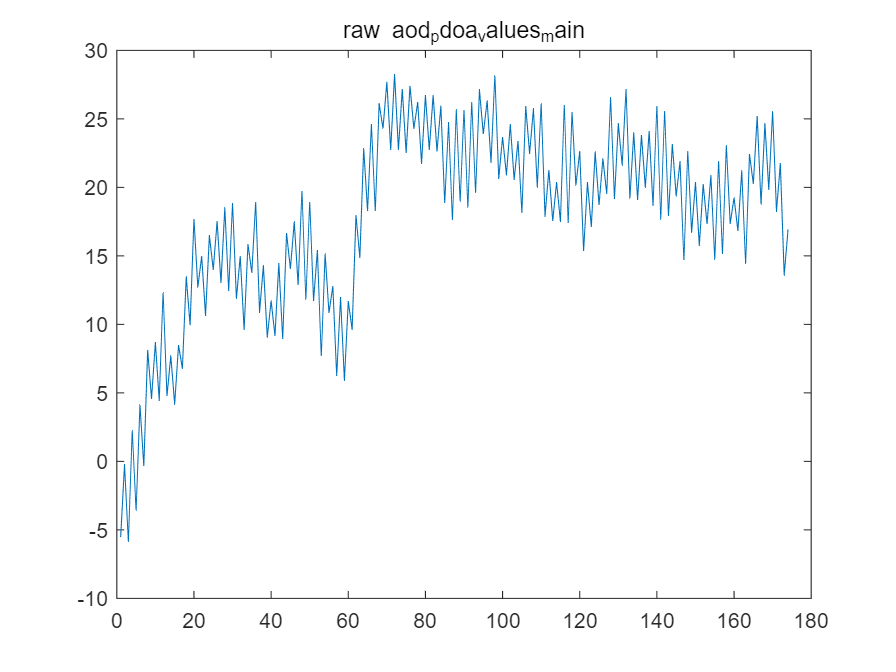

for i = 1:num_rounds
    aod_pdoa_values_main(i) = aod_pdoa_values_main(i) - aod_errors(i);
end
figure;
plot(aod_pdoa_values_main)
title('raw aod_pdoa_values_main');

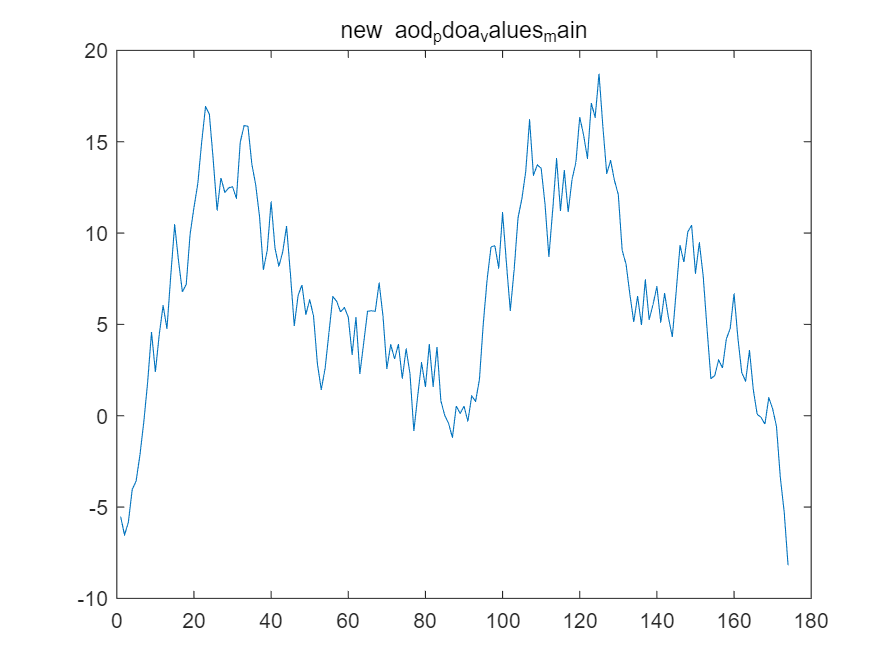

% 假设你已经有以下变量：
% aod_pdoa_values_main, aod_pdoa_values_secondary
% aod_degree_values_main, aod_degree_values_secondary
% 并且它们都是相位（rad）值或角度值序列

% === STEP 1: 相位展开（unwrap） ===
aod_pdoa_values_main = unwrap(aod_pdoa_values_main);
aod_pdoa_values_secondary = unwrap(aod_pdoa_values_secondary);
figure;
plot(aod_pdoa_values_main);
title('new aod_pdoa_values_main')

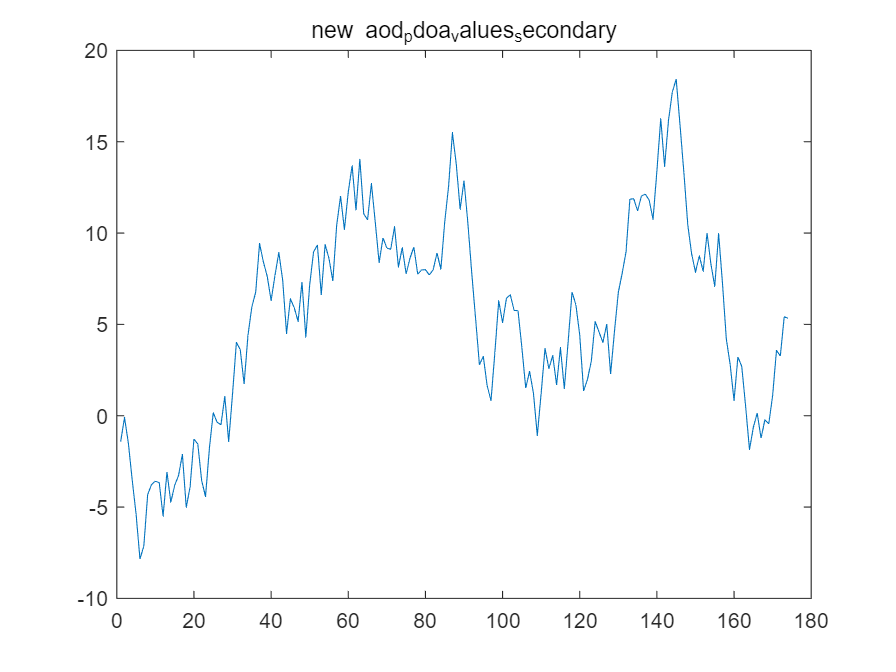

figure;
plot(aod_pdoa_values_secondary);
title('new aod_pdoa_values_secondary')

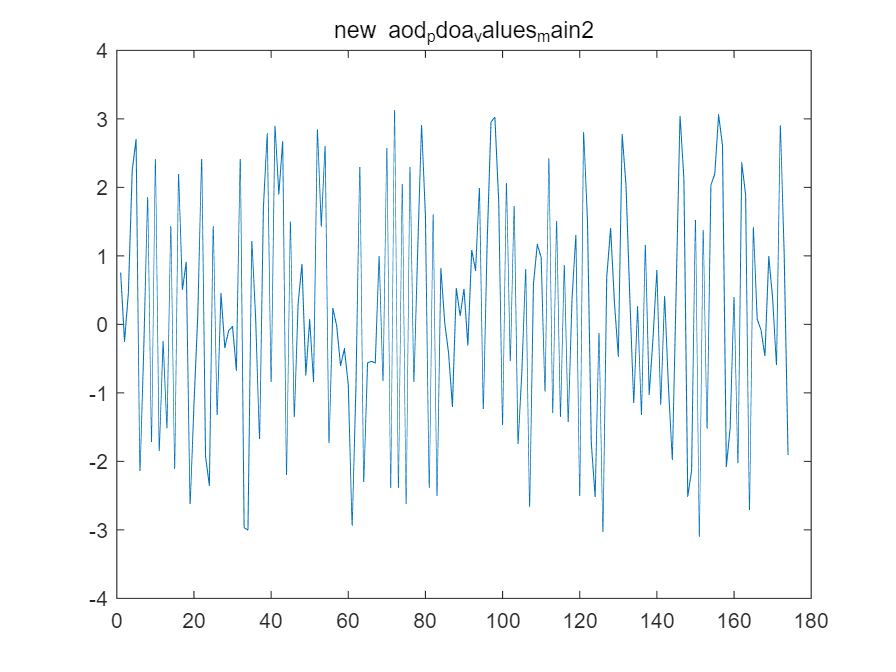

figure;
plot(mod(aod_pdoa_values_main+pi,2*pi)-pi);
title('new aod_pdoa_values_main2');


%有办法吗

% 假设你已有一组 wrap 后的 PDOA 相位差
% aod_pdoa_diff_wrapped = ...;

window_size = 10;           % 滑窗大小
residual_thresh = 0.6;      % 剔除残差阈值（rad）

[aod_est_rad, slope_series, cleaned_diff] = ...
    extract_aod_from_pdoa(aod_pdoa_values_main, window_size, residual_thresh);

函数或变量 'extract_aod_from_pdoa' 无法识别。


fprintf('🌟 最终估计的 AoD 相位差（rad）: %.4f\n', aod_est_rad);
fprintf('角度形式（deg）: %.2f°\n', rad2deg(aod_est_rad));


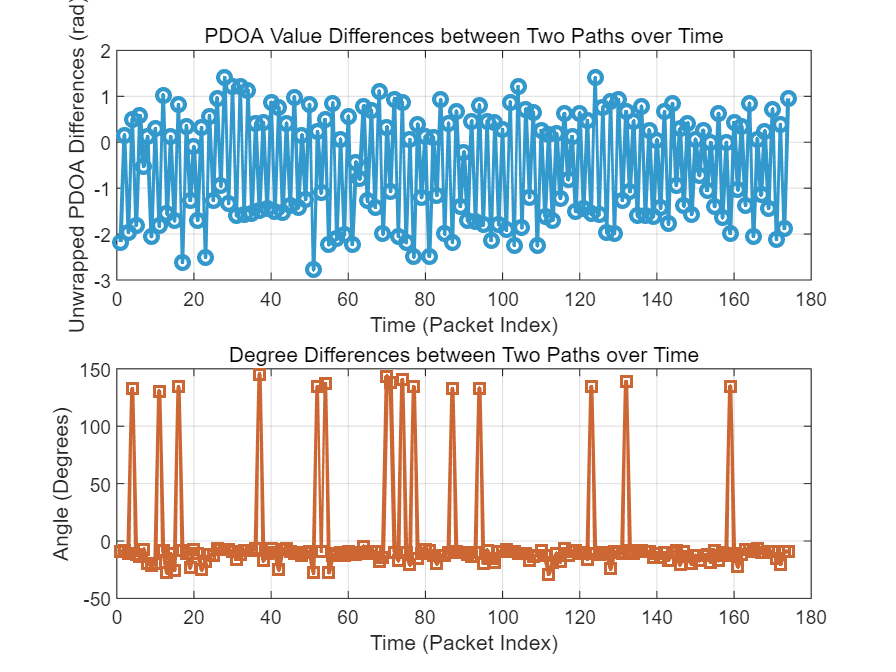


% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');

== 使用复数平均法 ==


fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);

PDOA 平均相位差 (rad): -0.5227


fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);

PDOA 相位差波动（类似标准差）(rad): 1.2936


fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);


Angle 平均角度差 (deg): -9.23


fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);

Angle 相位波动（类似标准差）(deg): 34.04


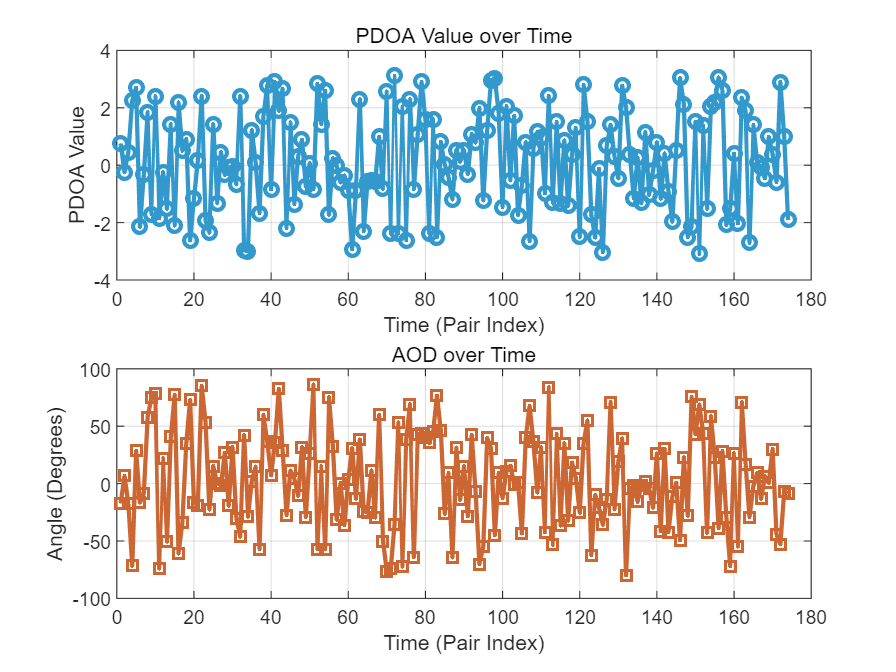

time = 1:length(aod_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, mod(aod_pdoa_values_main+pi,2*pi)-pi, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aod_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_main);
mean_degree = mean(aod_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_main);
std_degree = std(aod_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 6.61


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 5.45



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 3.30


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 41.55


time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
% aod_degree_diff= asin(aod_pdoa_diff * c / (2 * pi * antennaSpacing * frequency));
% aod_degree_diff = rad2deg(aod_pdoa_diff);
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)

aod_sin_diff =    -0.6919    0.0484   -0.6249    0.1586   -0.5742    0.1838   -0.1661    0.0378   -0.6531    0.0945   -0.5805    0.3264   -0.4957    0.0382   -0.5435    0.2604   -0.8314    0.1124   -0.4035   -0.0325   -0.5406    0.1009   -0.7961    0.1818   -0.4014    0.3052   -0.3032    0.4477   -0.4220    0.3874   -0.5074    0.3847   -0.5028    0.3576   -0.4936    0.1277   -0.4703    0.1356   -0.4573    0.2755   -0.4784    0.2397   -0.4875    0.1309   -0.4394    0.3130   -0.4539    0.0480   -0.3948    0.2613


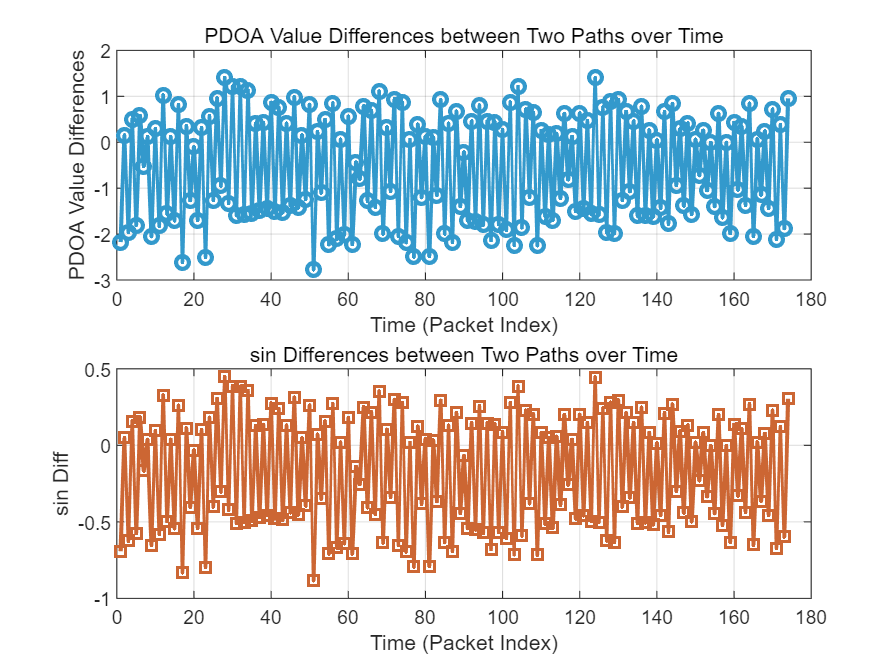

figure;
subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');
grid on;

subplot(2,1,2);
plot(time, aod_sin_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('sin Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('sin Diff');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_diff);
mean_sin = mean(aod_sin_diff);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_diff);
std_sin = std(aod_sin_diff);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -0.55


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.16



fprintf('\nsin 平均值: %.2f\n', mean_sin);


sin 平均值: -0.18


fprintf('sin 标准差: %.2f\n', std_sin);

sin 标准差: 0.37


%PDOA1.97,大约稳定在38.8°左右

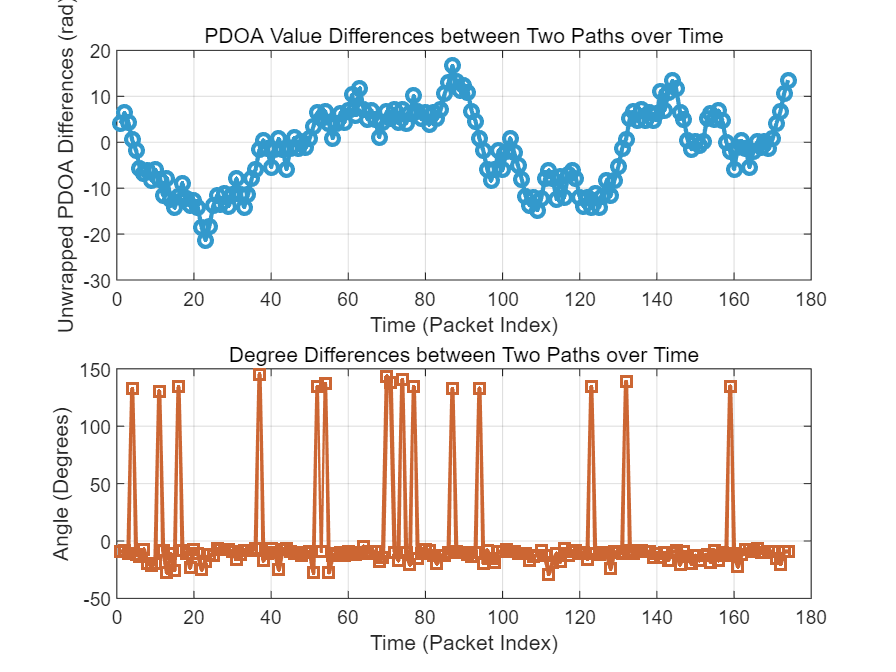

% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');

== 使用复数平均法 ==


fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);

PDOA 平均相位差 (rad): -0.5227


fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);

PDOA 相位差波动（类似标准差）(rad): 1.2936


fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);


Angle 平均角度差 (deg): -9.23


fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);

Angle 相位波动（类似标准差）(deg): 34.04


time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = abs(mod(aod_pdoa_diff + pi, 2*pi) - pi);
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)

aod_sin_diff =     0.6919    0.0484    0.6249    0.1586    0.5742    0.1838    0.1661    0.0378    0.6531    0.0945    0.5805    0.3264    0.4957    0.0382    0.5435    0.2604    0.8314    0.1124    0.4035    0.0325    0.5406    0.1009    0.7961    0.1818    0.4014    0.3052    0.3032    0.4477    0.4220    0.3874    0.5074    0.3847    0.5028    0.3576    0.4936    0.1277    0.4703    0.1356    0.4573    0.2755    0.4784    0.2397    0.4875    0.1309    0.4394    0.3130    0.4539    0.0480    0.3948    0.2613



% 弧度转换为角度
aod_degree_diff = rad2deg(aod_pdoa_diff);  % 注意这里不再使用asin公式
% aod_degree_diff = abs(aod_degree_values_secondary - aod_degree_values_main);


% ----------- 滤除异常值（使用Z-score法） -------------
% 对 PDOA 进行异常值剔除
z_pdoa = abs((aod_pdoa_diff - mean(aod_pdoa_diff)) / std(aod_pdoa_diff));
valid_idx_pdoa = z_pdoa < 3;  % 3σ内为正常值
%valid_idx_pdoa = 1 < aod_pdoa_diff
filtered_pdoa = aod_pdoa_diff(valid_idx_pdoa);
filtered_sin = aod_sin_diff(valid_idx_pdoa)

filtered_sin =     0.6919    0.0484    0.6249    0.1586    0.5742    0.1838    0.1661    0.0378    0.6531    0.0945    0.5805    0.3264    0.4957    0.0382    0.5435    0.2604    0.8314    0.1124    0.4035    0.0325    0.5406    0.1009    0.7961    0.1818    0.4014    0.3052    0.3032    0.4477    0.4220    0.3874    0.5074    0.3847    0.5028    0.3576    0.4936    0.1277    0.4703    0.1356    0.4573    0.2755    0.4784    0.2397    0.4875    0.1309    0.4394    0.3130    0.4539    0.0480    0.3948    0.2613



% 对 Degree 进行异常值剔除
z_degree = abs((aod_degree_diff - mean(aod_degree_diff)) / std(aod_degree_diff));
valid_idx_degree = z_degree < 3;
filtered_degree = aod_degree_diff(valid_idx_degree);

% 滤除后的时间轴（可选）
filtered_time_pdoa = time(valid_idx_pdoa);
filtered_time_degree = time(valid_idx_degree);
filtered_time_sin = time(valid_idx_pdoa)

filtered_time_sin =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


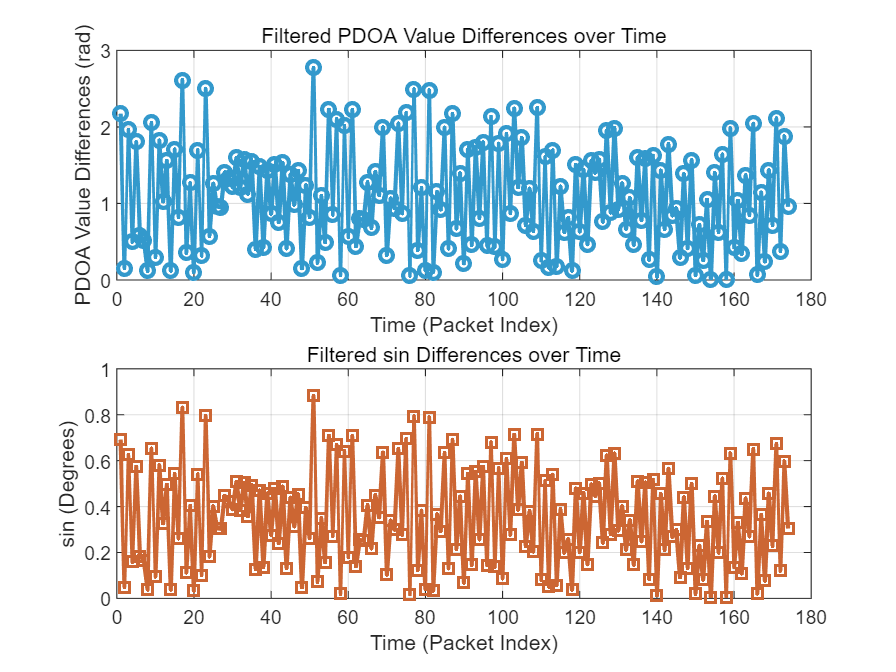

%这里直接用filterd_pdoa去估计filtered_time_sin的值了

% ---------------- 绘图 ----------------
figure;
subplot(2,1,1);
plot(filtered_time_pdoa, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value Differences over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences (rad)');
grid on;

subplot(2,1,2);
plot(filtered_time_pdoa, filtered_sin, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered sin Differences over Time');
xlabel('Time (Packet Index)');
ylabel('sin (Degrees)');
grid on;


% ---------------- 输出统计量 ----------------
fprintf('--- After Filtering ---\n');

--- After Filtering ---


fprintf('PDOA 平均值: %.4f rad\n', mean(filtered_pdoa));

PDOA 平均值: 1.0897 rad


fprintf('PDOA 标准差: %.4f rad\n', std(filtered_pdoa));

PDOA 标准差: 0.6785 rad



fprintf('\nsin 平均值: %.2f°\n', mean(filtered_sin));


sin 平均值: 0.35°


fprintf('sin 标准差: %.2f°\n', std(filtered_sin));

sin 标准差: 0.22°


function arr = swapElements(arr, i, j)
    temp = arr(i);
    arr(i) = arr(j);
    arr(j) = temp;
end